Stabilità

clear
clf

q_point = [8e-3 3]; %Ic VCE
op_freq = 1.6e9;
lin_freq = 3e7:10e6:5e9;

Z0=50; %ohm

bfp640 = read(rfckt.amplifier , ['BFP640/BFP640_w_noise_VCE_3.0V_IC_8.0mA.s2p']);
[s_par , freq] = extract(bfp640 , 'S_parameters');

[mu,muprime] = stabilitymu(s_par);
figure
plot(freq/1e9,mu,'--',freq/1e9,muprime,'r')

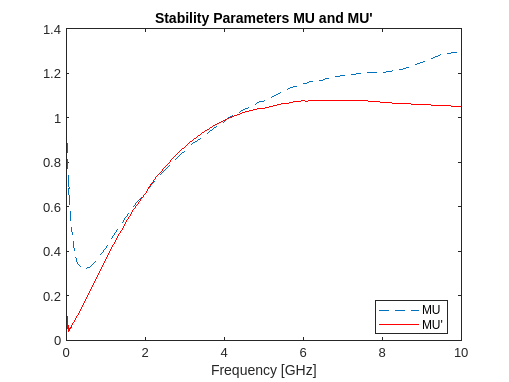

legend('MU',"MU'",'Location','Best') 
title("Stability Parameters MU and MU'")
xlabel('Frequency [GHz]')

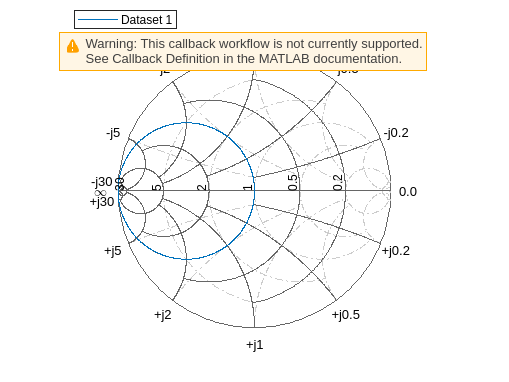

Error using rfdata.data/circle>validate_circle
No Resistance Circle exists that meets the criteria
specified in the type/value pair {'R',[NaN]}.

Error in rfdata.data/circle (line 172)
    validate_circle(cen,rad,varargin{kk},varargin{kk+1},desc,tempx,tempy);

Error in rfckt.rfckt/circle (

AllGammaS = calculate(bfp640,'GammaMS','none');

gammas = AllGammaS{1}(freq == op_freq);

figure
sp = smithplot;
sp.GridType = 'YZ';

Za = (0.177-0.383j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , "R", real(gamma2z(gammas , 1)) , sp);

hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Za),'k.','MarkerSize',16);
text(real(z2gamma(Za))+0.05,imag(z2gamma(Za))+0.05,'A','FontSize', 12, ...
    'FontUnits','normalized');
hold off
imag(Za)
C_shunt = imag(1/Za)/(2*pi*op_freq)
C_series = abs(imag(gamma2z(gammas) - Za))/(2*pi*op_freq)

% C_shunt = 600e-15
% C_series = 2.55e-9

input_match = rfckt.cascade('Ckts', ...
    {rfckt.shuntrlc('C',C_shunt),rfckt.seriesrlc('L',C_series)});

Output match

AllGammaL = calculate(bfp640,'GammaML','none');
gammal = AllGammaL{1}(freq == op_freq);


figure
sp2 = smithplot;
sp2.GridType = 'YZ';


Zb = (1-1.7134j)*Z0

circle(bfp640 , op_freq , "G" , 1 , "G" , real(1/gamma2z(gammal , 1)) , sp2);
hold on
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Zb),'k.','MarkerSize',16);
text(real(z2gamma(Zb))+0.05,imag(z2gamma(Zb))+0.05,'B','FontSize', 12, ...
    'FontUnits','normalized');

hold off
imag(gamma2z(gammal,1) - Zb/50);
L_shunt = 50/(abs(imag(1/gamma2z(gammal,1) - 50/Zb)*2*pi*op_freq))
L_series = 1/abs(imag(Zb)*2*pi*op_freq)

% L_shunt = 27e-9
 L_series = 1e-12

output_match = rfckt.cascade('Ckts', ...
  {rfckt.shuntrlc('L',L_shunt),rfckt.seriesrlc('C',L_series)});

LNA = rfckt.cascade('ckts', ...
    {input_match,bfp640,output_match});

analyze(LNA,lin_freq);

% LNA_sper = read(rfckt.amplifier , 'L_NO_COP.s2p');
% analyze(LNA_sper,lin_freq);

figure,plot(LNA,'S11','dB');
title("S11 amplificatore L-Matchting")
hold on
%plot(LNA_sper,'S11','dB');
hold off

figure,plot(LNA,'S22','dB');
title("S22 amplificatore L-Matching")
hold on
%plot(LNA_sper,'S22','dB');
hold off

figure,plot(LNA,'S21','dB');
title("S21 (Guadagno) amplificatore L-Matchting")
hold on
%plot(LNA_sper,'S21','dB');
hold off